# **IO144 - Analog Output and Digital Loopback**

This example shows you how to do a test with the IO144 I/O module in order to verify the basic functionality of some of the analog output channels and digital Input and output channels.

The IO144 is a 16-bit analog module with 8 analog outputs, and 20 digital TTL I/O lines individually configurable as inputs or outputs.

The Simulink model features the [IO144 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io144_setup_v2), [IO144 Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io144_analog_output_v2),  [IO144 Digital input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io144_digital_input_v2) and [IO144 Digital output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io144_digital_output_v2) blocks. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO144 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

- Oscilloscope

### Pin Mapping/Connection Diagram/Test Setup

This example outputs a sine wave signal on the analog voltage outputs that can be visualized using an oscilloscope. On the digital part, a pulse generator is connected to the digital outputs.

On the terminal board of the IO144 I/O module, connect Pin 1, the analog output channel 1, to the probe input clip and Pin 35, the ground pin, to the ground clip of the oscilloscope. 

The pulse is sampled with the digital inputs.On the terminal board connect the digital output pins with the digital input pins. T

The wiring is shown on the picture below:

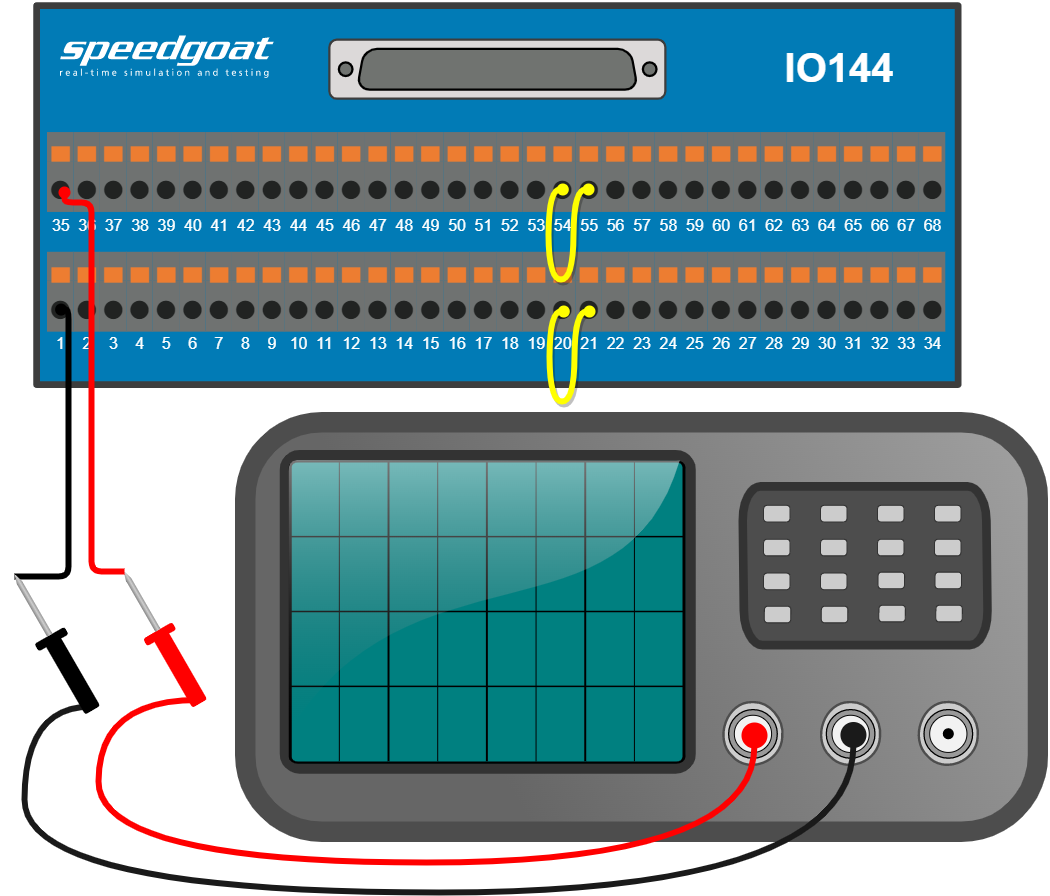

[IO144 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io144_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO144_AnalogDigitalLoopback';
open_system(modelName);

### Model Description

Analog output channels 1 and 2, as well as all 4 digital I/O channels are enabled in the IO144 Setup block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;
pause(10);
% Wait a few seconds and then stop the real-time application on the target machine
tg.stop;

### Check the Results

**Analog I/O Outputs**

Once the model runs, you should be able to see the output voltage from the IO144. The output signal is a sine wave with frequency = 20 Hz, amplitude +-2 V on channel 1.

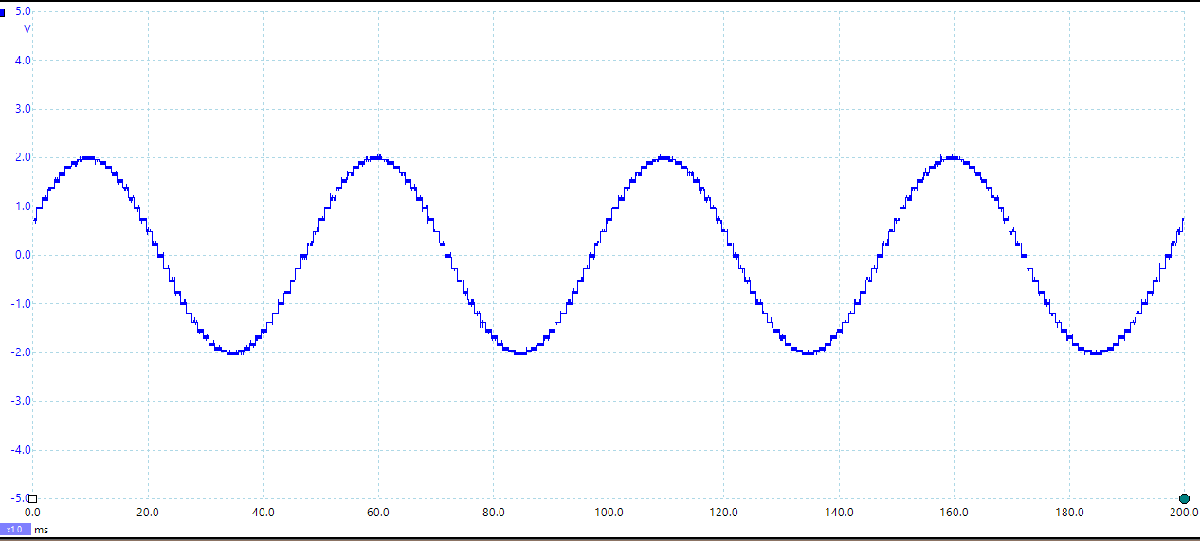

**Digital I/O Loopback**

In the digital input scope you can see the four pulse generator signals sent from digital output channels 1 and 2 to digital input channels 3 and 4 respectively.

The different duty cycles and the y-axis shift are introduced to enhance the visibility of the different channels.

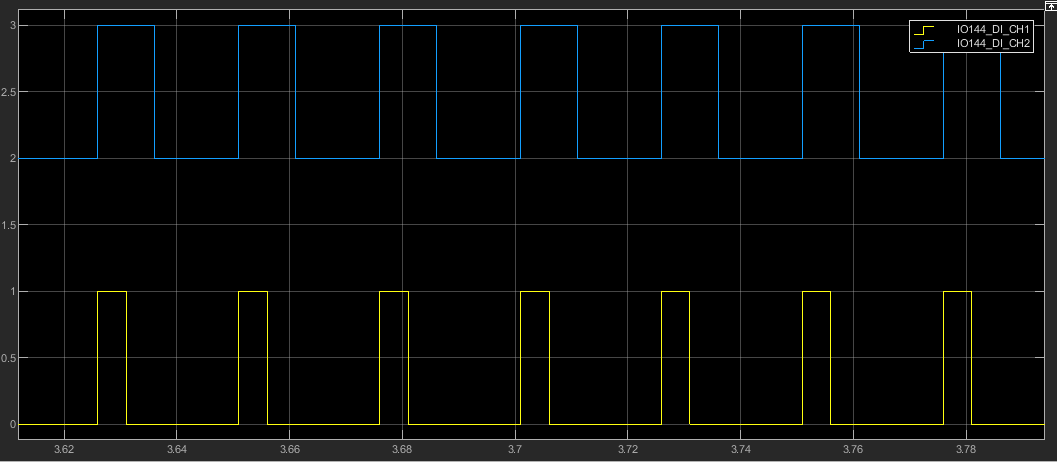

## Additional References

- [IO144 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io144)